**Table 1: **

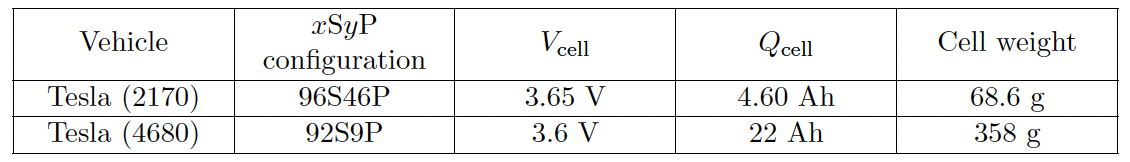

**Table 2:** 

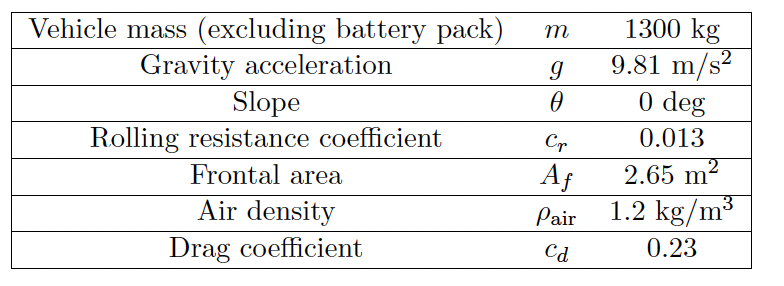

clc
clear
close all

% Initial Parameters:

% Electric Vehicle Battery Performance Analysis
% Constants
vehicle_base_mass = 1300;  % kg
g = 9.81;       % m/s^2
theta = 0;      % road slope (degrees)
cr = 0.013;     % rolling resistance coefficient
Af = 2.65;      % frontal area (m^2)
cd = 0.23;      % drag coefficient
ro_air = 1.2;  % air density (kg/m^3)
eta = 0.8;      % powertrain efficiency
ca = 0.12;      % auxiliary coefficient

% Battery Pack Configurations
battery_configs = struct(...
    'type', {'2170', '4680'}, ...
    'series', {96, 92}, ...
    'parallel', {46, 9}, ...
    'cell_voltage', {3.65, 3.6}, ... % in Voltage (v)
    'cell_capacity', {4.60, 22}, ... % in Ah
    'cell_weight', {68.6, 358} ... % in grams (g)
);

**Extracting the data:**


% Load Drive Cycle Data
udds_data = readmatrix('uddscol.csv');
us06_data = readmatrix('us06col.csv');

% Convert Speed and Compute Acceleration
udds_time = udds_data(:, 1); % in Sec
udds_speed = udds_data(:, 2) * 0.44704;  % mph to m/s
udds_accel = gradient(udds_speed, udds_time); % m/s^2

us06_time = us06_data(:, 1); % in Sec
us06_speed = us06_data(:, 2) * 0.44704; % mph to m/s
us06_accel = gradient(us06_speed, us06_time); % m/s^2

**Question 1**:

Compute and plot the duty cycles P(t), pack current I(t), and SOC s(t) for the UDDS and US06 drive cycles using the two EV battery packs specified in Table 1 and the vehicle dynamics provided in Table 2.

(a) Duty cycle (P(t) vs. t). Compute the duty cycles using the power equation in (4) and the vehicle dynamics provided in Table 2. Calculate the battery pack weights based on Table 1 and include them in the total vehicle mass for your calculations.

**Answer:**

# **Duty cycle for Tesla (2170) and Tesla (4680) Battery Pack:**

loop 1 => Tesla (2170); loop 2 => Tesla (4680)

% Battery Performance Analysis
for i = 1:length(battery_configs)
    config = battery_configs(i);
    
    % Pack Calculations
    battery_weight = config.series * config.parallel * config.cell_weight / 1000
    total_mass = vehicle_base_mass + battery_weight

    % UDDS Drive Cycle Analysis
    P_udds = power_demand(udds_speed, udds_accel, total_mass, g, cr, Af, cd, ro_air, theta);
    % US06 Drive Cycle Analysis
    P_us06 = power_demand(us06_speed, us06_accel, total_mass, g, cr, Af, cd, ro_air, theta);


**Plotting Duty Cycle:**

battery_weight = 302.9376

total_mass = 1.6029e+03

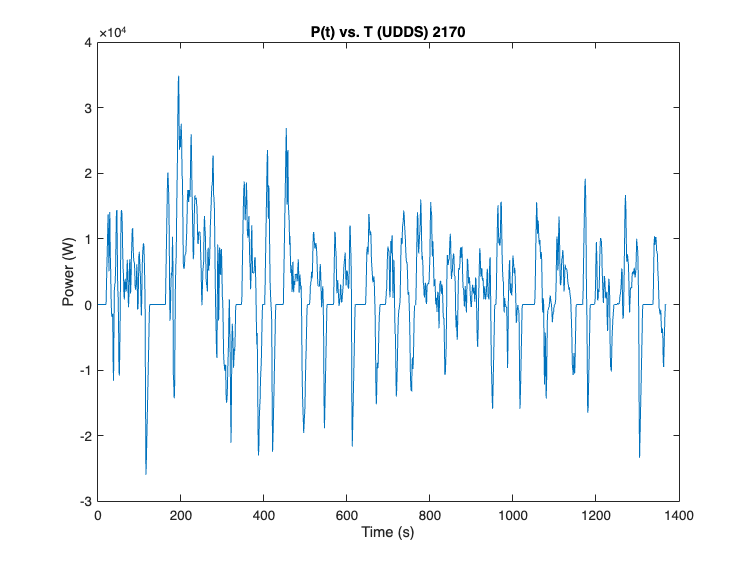

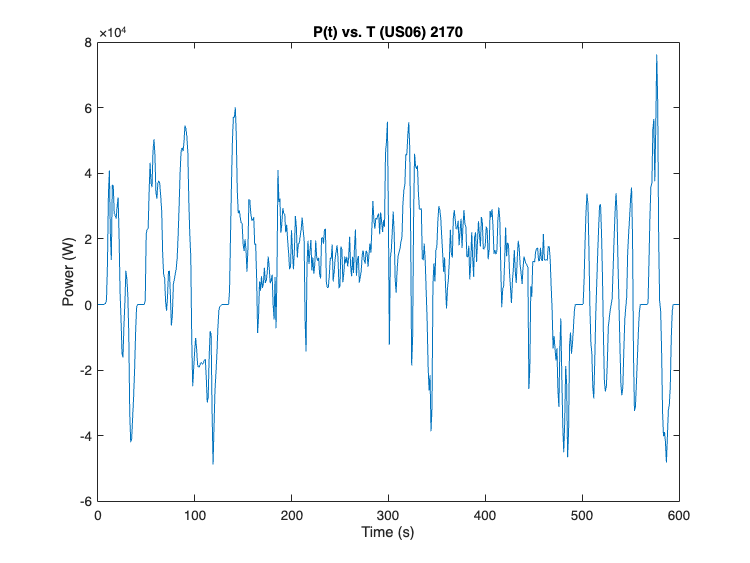

battery_weight = 296.4240

total_mass = 1.5964e+03

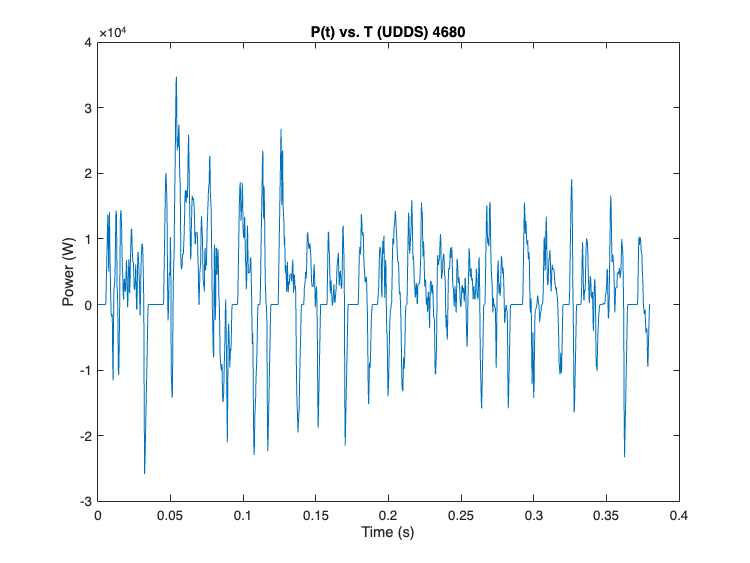

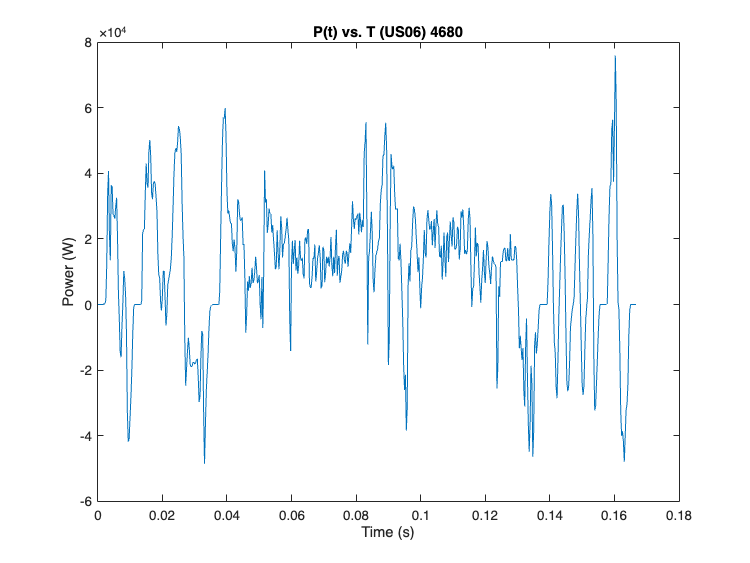


    % Plotting Duty Cycle:
    % UDDS Plot
    figure;
    plot(udds_time, P_udds);
    title(['P(t) vs. T (UDDS) ' config.type]);
    xlabel('Time (s)'); ylabel('Power (W)');

    hold on 
    % US06 Plot
    figure;
    plot(us06_time, P_us06);
    title(['P(t) vs. T (US06) ' config.type]);
    xlabel('Time (s)'); ylabel('Power (W)');

(b) Pack current (I(t) vs. t). Compute the pack current by assuming P(t) = I(t)Vpack, where Vpack = x × Vcell, and x is the number of cells in series.

**Answer:**

# **Pack current for Tesla (2170) and Tesla (4680) Battery Pack:**

    Vpack = config.series * config.cell_voltage

    % current - UDDS
    I_udds = P_udds / Vpack;

    % current - US06 
    I_us06 = P_us06 / Vpack;

**Plotting Pack Current:**

Vpack = 350.4000

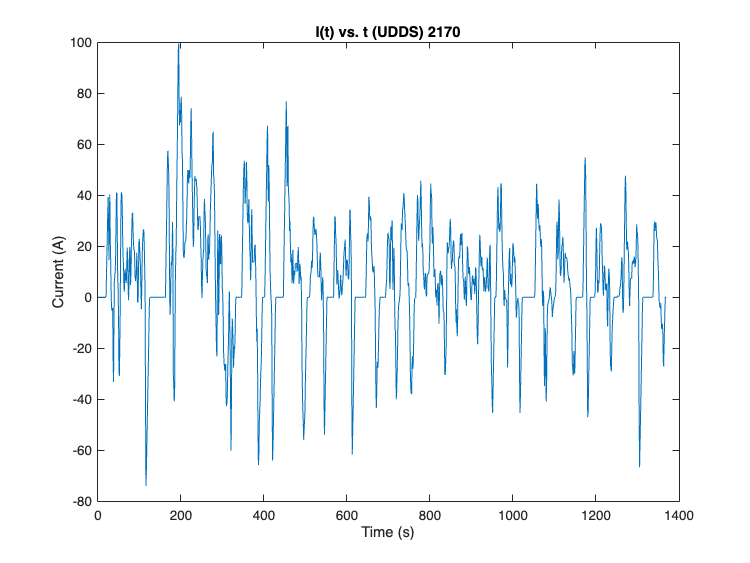

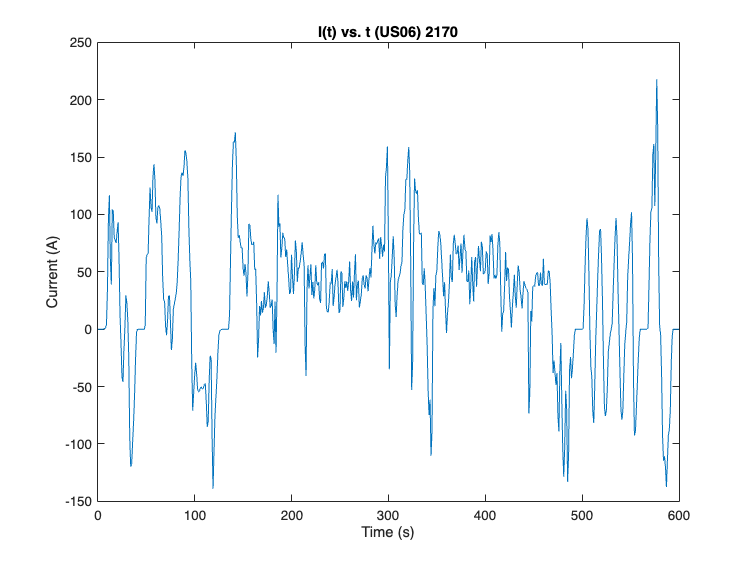

Vpack = 331.2000

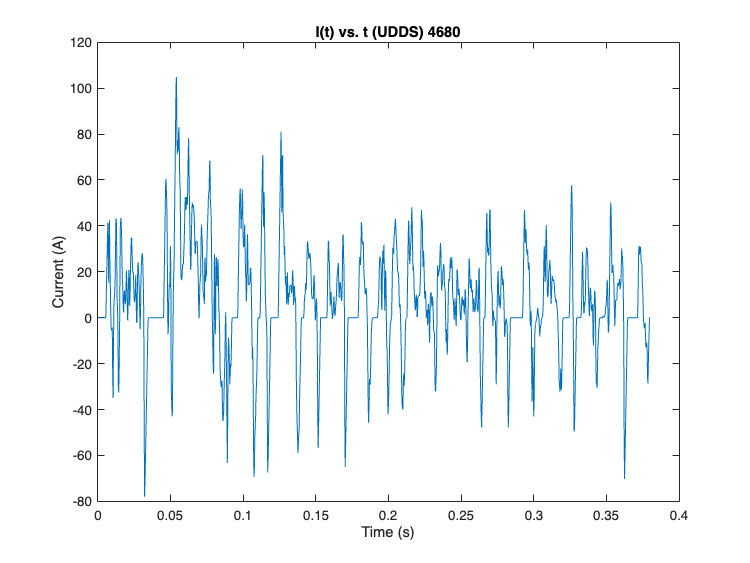

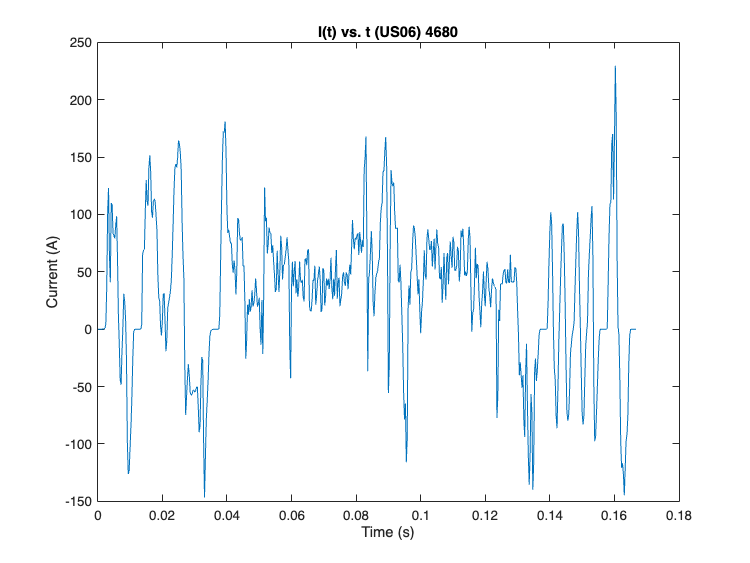

    % Plotting Pack Current:
    % UDDS Plot
    figure;
    plot(udds_time, I_udds);
    title(['I(t) vs. t (UDDS) ' config.type]);
    xlabel('Time (s)'); ylabel('Current (A)');


    hold on 
    % US06 Plot
    figure;
    plot(us06_time, I_us06);
    title(['I(t) vs. t (US06) ' config.type]);
    xlabel('Time (s)'); ylabel('Current (A)');

(c) Pack SOC (s(t) vs. t). Compute the pack SOC using the Coulomb counting equation:

**Answer:**

# **Pack SOC for Tesla (2170) and Tesla (4680) Battery Pack:**

    Qpack = config.parallel * config.cell_capacity % in (Ah)
    initial_soc = 0.8;

    % SOC - UDDS 
    soc_udds = comp_soc(initial_soc, I_udds, Qpack, udds_time);

    % SOC - US06 
    soc_us06 = comp_soc(initial_soc, I_us06, Qpack, us06_time);

    

  **Plotting Pack SOC:**

Qpack = 211.6000

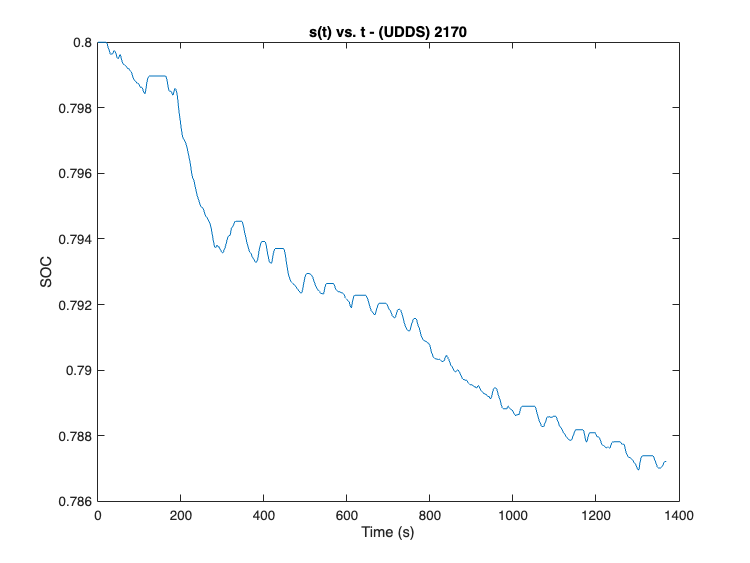

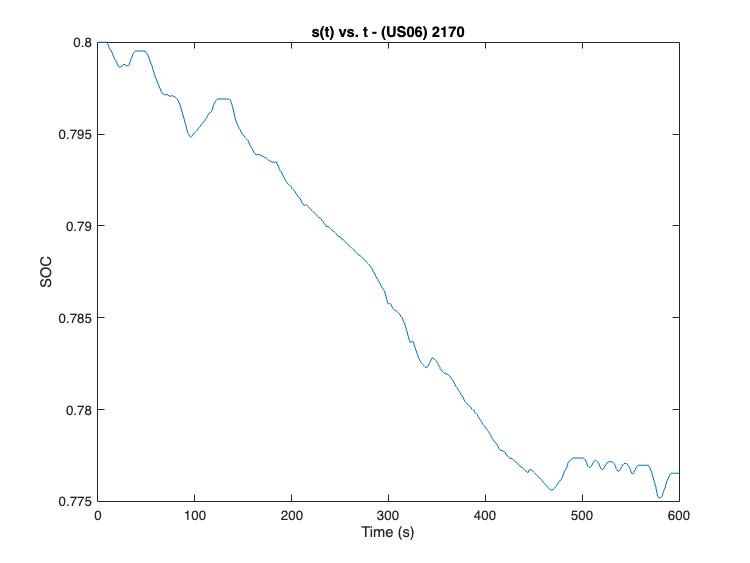

Qpack = 198

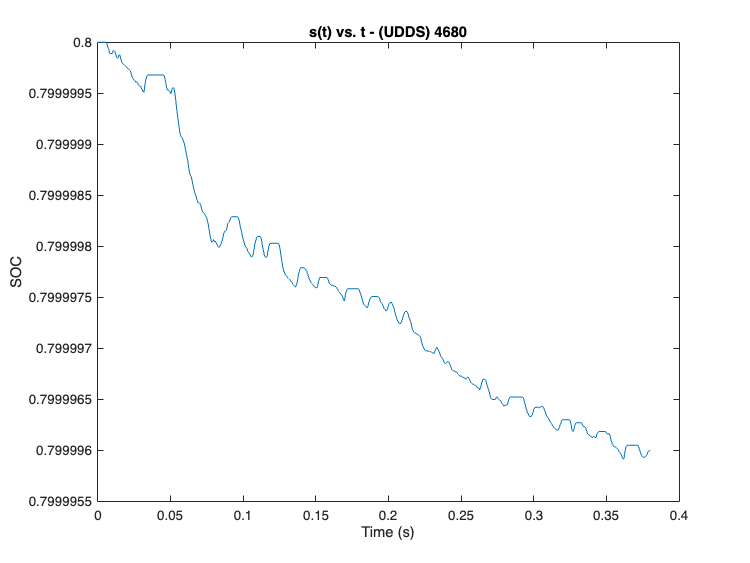

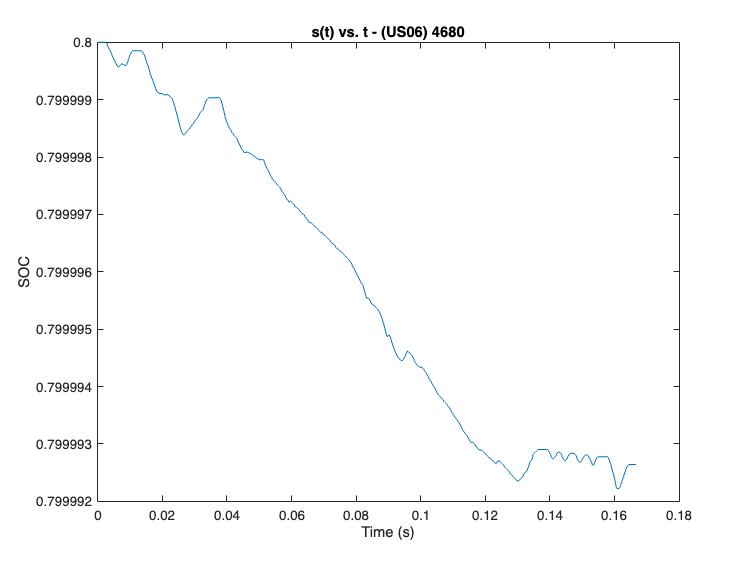

    % Plotting Pack SOC:
    % UDDS Plot
    figure;
    plot(udds_time, soc_udds);
    title(['s(t) vs. t - (UDDS) ' config.type]);
    xlabel('Time (s)'); ylabel('SOC');


    hold on 
    % US06 Plot
    figure;
    plot(us06_time, soc_us06);
    title(['s(t) vs. t - (US06) ' config.type]);
    xlabel('Time (s)'); ylabel('SOC');

**Question 2**:

Estimate the UDDS and US06 drive cycle ranges using (3) for the two battery packs specified in Table 1 and the vehicle dynamics provided in Table 2.

    • Similar to Question 1, calculate the battery pack weights based on Table 1 and include them in the total vehicle mass for your calculations.

    • Assume the powertrain efficiency and auxiliary coefficient are η = 0.8 and ca = 0.12, respectively, to compute the vehicle energy consumption.

    Ecell = config.cell_voltage * config.cell_capacity; % in (Wh)
    Epack = config.series * config.parallel * Ecell; % in (Wh)

    % UDDS Drive Cycle Analysis
    udds_time = udds_time/3600; % converting the time to hours

    E_d_udds = trapz(udds_time, max(P_udds, 0)) % in watt per hour (Wh)
    E_c_udds = trapz(udds_time, min(P_udds, 0)) % in watt per hour (Wh)
    E_vehicle_udds = comp_energy(E_d_udds, E_c_udds, eta, ca); % in watt per hour (Wh)
    
    D_udds = trapz(udds_time * 3600, udds_speed) / 1000; % total distance in kilometer (km)
    E_con_udds = (E_vehicle_udds / D_udds); % in Wh/km
    range_udds = Epack / E_con_udds; % in km
    
    % US06 Drive Cycle Analysis
    us06_time = us06_time/3600; % converting the time to hours
   
    E_d_us06 = trapz(us06_time, max(P_us06, 0)) % in Wh
    E_c_us06 = trapz(us06_time, min(P_us06, 0)) % in Wh
    E_vehicle_us06 = comp_energy(E_d_us06, E_c_us06, eta, ca); % in Wh
    
    D_us06 = trapz(us06_time * 3600, us06_speed) / 1000; % total distance in kilometer (km)
    E_con_us06 = (E_vehicle_us06 / D_us06); % Wh/km
    range_us06 = Epack / E_con_us06; % in km

    % Results Output
    fprintf('Tesla (%s) Battery Pack Results:\n', config.type);
    fprintf('  Ecell: %.2f Wh, Epack: %.2f Wh', Ecell, Epack);
    fprintf('  UDDS Range: %.2f km, Energy Consumption: %.2f Wh/km\n', range_udds, E_con_udds);
    fprintf('  US06 Range: %.2f km, Energy Consumption: %.2f Wh/km\n\n', range_us06, E_con_us06);

end

E_d_udds = 1.5643e+03

E_c_udds = -616.2763

E_d_us06 = 2.4019e+03

E_c_us06 = -661.7878

Tesla (2170) Battery Pack Results:


  Ecell: 16.79 Wh, Epack: 74144.64 Wh

  UDDS Range: 690.82 km, Energy Consumption: 107.33 Wh/km


  US06 Range: 439.08 km, Energy Consumption: 168.86 Wh/km



E_d_udds = 0.4330

E_c_udds = -0.1704

E_d_us06 = 0.6655

E_c_us06 = -0.1829

Tesla (4680) Battery Pack Results:


  Ecell: 79.20 Wh, Epack: 65577.60 Wh

  UDDS Range: 612.95 km, Energy Consumption: 106.99 Wh/km


  US06 Range: 389.16 km, Energy Consumption: 168.51 Wh/km



# **Functions:**

**Function to compute state of charge s(t):**

    % State of Charge Computation Function
function SOC = comp_soc(initial_soc, current, capacity, time)
    SOC = zeros(size(time));
    SOC(1) = initial_soc;
    time = time /3600; % to convert sec to hours
    for i = 2:length(time)
        SOC(i) = SOC(i-1) - ((time(i) - time(i-1)) * (current(i)) / capacity);
    end
end

**Function to compute power demand P(t):**

% compute power demand P(t)
function P = power_demand(speed, accel, mass, g, cr, Af, cd, ro_air, theta)
    P = (mass * g * sin(deg2rad(theta)) + cr * mass * g * cos(deg2rad(theta)) + ...
         0.5 * ro_air * cd * Af .* speed.^2 + mass .* accel) .* speed;
end

**Energy Consumption Computation Function: **

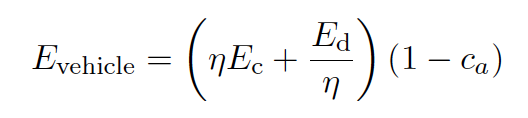

% Energy Consumption Computation Function
function E_vehicle = comp_energy(E_d, E_c, eta, ca)
    E_vehicle = ((eta * E_c) + (E_d / eta)) * (1 - ca);
end